# Matlab live script for analyzing exploration distance and time prior to trial initiaion during the cued conflict task.

You wil require the following files to run this code:

- CSV file created by the DLC.

- Video file used in the DLC.

## Batch Analysis

## Import DLC data

Import all csv files

clear all;close all;clc;

% Get all CSV files in the current folder
csvFiles = dir('*.csv');

% Loop through each CSV file
 for i = 1:length(csvFiles)
% i = 2
    % Get file name
    fileName = csvFiles(i).name;

    % Get path name
    pathName = csvFiles(i).folder;
    
    % Display progress
    fprintf('Processing file: %s\n', fileName);

opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["scorer", "nose_x", "nose_y", "nose_accuracy", "centre_x", "centre_y", "centre_accuracy", "tail_x", "tail_y", "tail_accuracy", "shelter_x", "shelter_y", "shelter_accuracy"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
azopts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DLCraw = readtable(fullfile(pathName,fileName),opts);
clear opts

### Create a timetable from the DLC data.

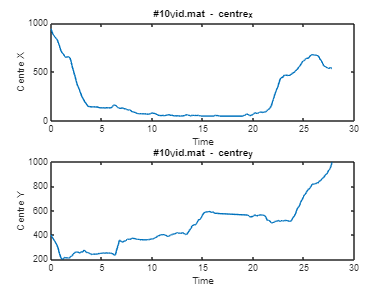

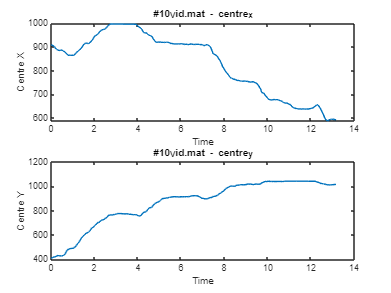

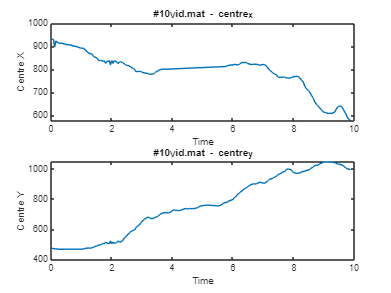

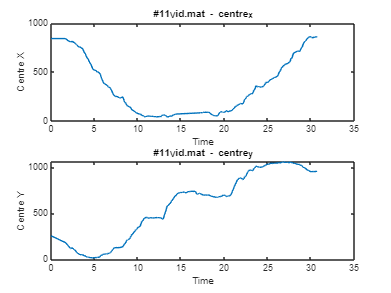

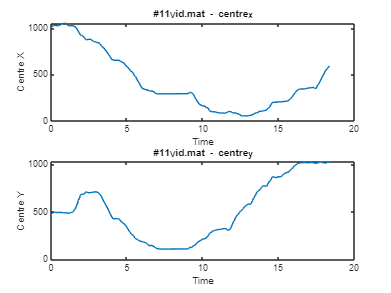

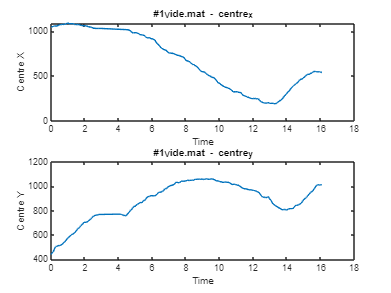

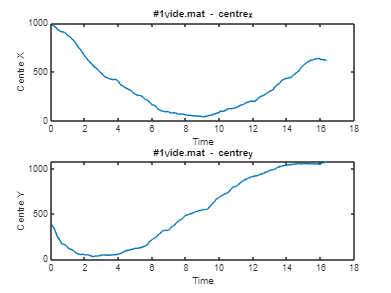

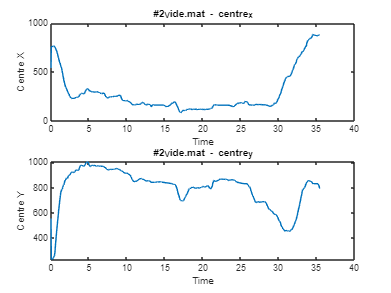

DLCdata = table(DLCraw.centre_x, DLCraw.centre_y,'VariableNames', {'centre_x', 'centre_y'});

% Get number of rows
nRows = height(DLCdata);

% Create fractional time vector assuming 25 Hz (i.e., 1/25 seconds per row)
DLCdata.Time = (0:nRows-1)' / 25;

DLCdata;

Plot Centre X and Y

% plot centre_x
figure
subplot(2,1,1)
plot(DLCdata.Time,DLCdata.centre_x)
title ('Corrected centre_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('X coordinate')

% plot centre_y
figure
subplot(2,1,1)
plot(DLCdata.Time,DLCdata.centre_y)
title ('Corrected centre_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Y coordinate')

## Distance Elapsed

total_distance = [];
% Calculate the differences between consecutive points
dx = diff(DLCdata.centre_x);
dy = diff(DLCdata.centre_y);

% Compute the distance for each segment
distances = sqrt(dx.^2 + dy.^2);

% Sum up all distances to get the total distance traveled in pixels
total_distance = sum(distances);

% Calculate total distance travelled in meters
% width of shelter in pixels = 170 pixels
% width of shelter in meters = 0.1 m
pixelsperm = 170/0.1;

total_distance_meters = total_distance/pixelsperm;

% Display the total distance
disp(['Total distance traveled: ', num2str(total_distance_meters)]);

## Time Elapsed

lastTimestamp = DLCdata.Time(end);

% Display the time elapsed
disp(['Time elapsed: ', num2str(lastTimestamp)]);

#### Save matlab file

% Extract base name from CSV file
[~, nameOnly, ~] = fileparts(csvFiles(i).name);

% Get the first 9 characters (or fewer if name is shorter)
baseName = nameOnly(1:min(9, length(nameOnly)));

% Save the desired variables using that name
save([baseName '.mat']);

 end

### Plot all the data to check the tracking

% Get all .mat files in the current folder
matFiles = dir('*.mat');

% Loop through each file
for i = 1:length(matFiles)
    % Get the filename
    fileName = matFiles(i).name;

    % Load the .mat file
    data = load(fileName);

    % Check if DLCdata exists
    if isfield(data, 'DLCdata')
        % Extract DLCdata
        DLCdata = data.DLCdata;

        % Create a new figure for each file
        figure;

        % Plot centre_x
        subplot(2,1,1);
        plot(DLCdata.Time, DLCdata.centre_x);
        xlabel('Time');
        ylabel('Centre X');
        title([fileName ' - centre_x']);

        % Plot centre_y
        subplot(2,1,2);
        plot(DLCdata.Time, DLCdata.centre_y);
        xlabel('Time');
        ylabel('Centre Y');
        title([fileName ' - centre_y']);
    else
        warning('DLCdata not found in %s', fileName);
    end
end

### Compile data from all trials 

% Get all .mat files in the current folder
matFiles = dir('*.mat');

% Preallocate arrays
fileNames_data = cell(length(matFiles), 1);
totalDistances_data = nan(length(matFiles), 1);
lastTimestamps_data = nan(length(matFiles), 1);

% Loop through each file
for i = 1:length(matFiles)
    % Get the filename
    fileName = matFiles(i).name;

    % Load only the desired variables
    data = load(fileName, 'total_distance_meters', 'lastTimestamp');

    % Store the filename
    fileNames_data{i} = fileName;

    % Extract and store total distance if it exists
    if isfield(data, 'total_distance_meters')
        totalDistances_data(i) = data.total_distance_meters;
    end

    % Extract and store last timestamp if it exists
    if isfield(data, 'lastTimestamp')
        lastTimestamps_data(i) = data.lastTimestamp;
    end
end

% Create the summary table
beforeTrialData = table(fileNames_data, totalDistances_data, lastTimestamps_data, ...
    'VariableNames', {'fileName', 'total_distance_meters', 'lastTimestamp'});

writetable(beforeTrialData, 'beforeTrialData.xlsx');